clear;

## load model

init_Galton_Board;
x_init = x0_ball*(rand()-0.5);  % [mm] initial pos.

## set up simulation

N = 500;
% N = 5;
X  = zeros(1,N);
Xi = X;

## simulate and gather results

open_system('Galton_Board_v3')
sys = gcs;
set_param(sys,"FastRestart","on");
for i = 1:N
  if mod(i,10) == 0
    i
  end
  x_init = x0_ball*(rand()-0.5);  % [mm] initial pos.
  out = sim('Galton_Board_v3');
  X(i) = out.yout{1}.Values.Data(end);
  Xi(i) = x_init;
end

i = 10

i = 20

i = 30

i = 40

i = 50

i = 60

i = 70

i = 80

i = 90

i = 100

i = 110

i = 120

i = 130

i = 140

i = 150

i = 160

i = 170

i = 180

i = 190

i = 200

i = 210

i = 220

i = 230

i = 240

i = 250

i = 260

i = 270

i = 280

i = 290

i = 300

i = 310

i = 320

i = 330

i = 340

i = 350

i = 360

i = 370

i = 380

i = 390

i = 400

i = 410

i = 420

i = 430

i = 440

i = 450

i = 460

i = 470

i = 480

i = 490

i = 500

set_param(sys,"FastRestart","off");

## plot histogram

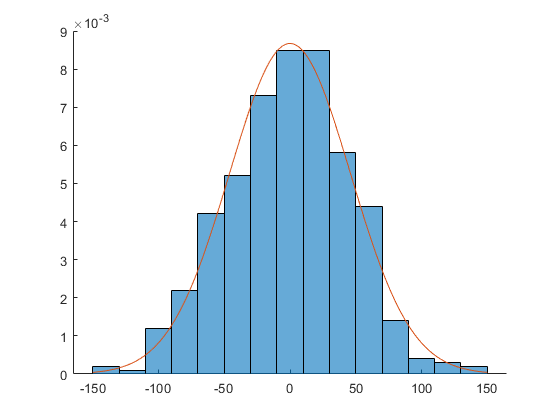

figure(101); clf;
hold on
histogram(X,[-150:20:150],'Normalization','pdf');
x = [-150:150];
y = normpdf(x,0,46);
plot(x,y)

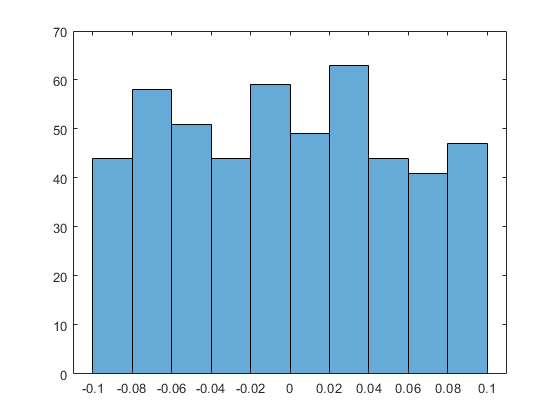


figure(102);
histogram(Xi);

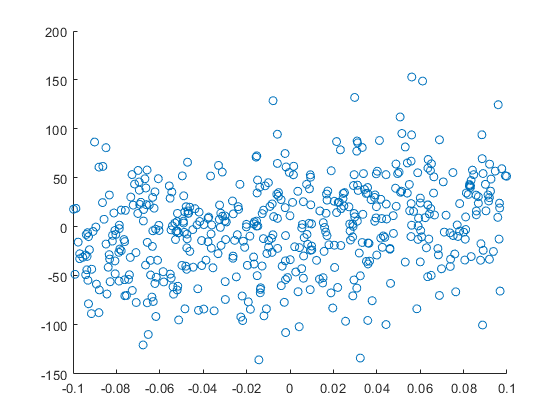


figure(103);
scatter(Xi,X);

*Copyright 2021 The MathWorks, Inc.*